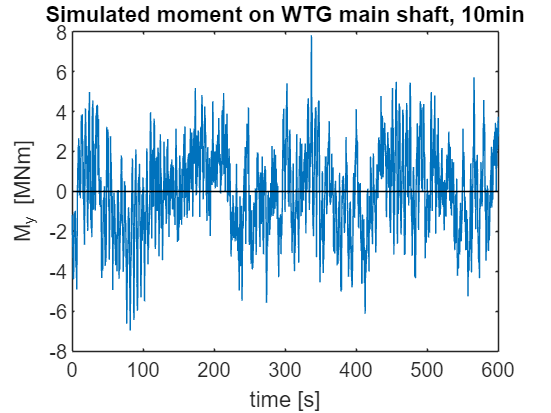

% Advanced Metal Fatigue: Exercise 4 - Rainflow counting
clc; clear variables; close all;

% load time series
load My

figure
plot(t,My); hold on
plot([1 t(end)],[0 0],'k')
ylabel('M_y [MNm]')
xlabel('time [s]')
title('Simulated moment on WTG main shaft, 10min')




%% 1. Calculate stress-time series
S_per_M = 24.4; % transfer function [MPa/MNm]
S = My*S_per_M % stress-time series [MPa]

S =                -31.8702125
               -29.9837875
                -27.951725
                  -27.9807
                -33.728425
                -41.420525
               -47.9223625
               -53.0600875
               -56.1085625
               -56.9503625


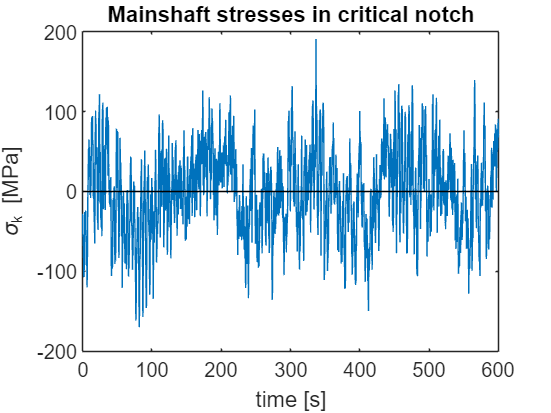


figure
plot(t,S); hold on
plot([1 t(end)],[0 0],'k')
ylabel('\sigma_{k} [MPa]')
xlabel('time [s]')
title('Mainshaft stresses in critical notch')



%% 2. Extract load cycles
[dS, Sm] = rainflow(S);
%Sa = dS/2; % convert stress ranges to amplitudes if needed
nS = length(dS); % no. extracted load cycles 


%% 3. Max stress range
max_stress_range = max(dS)

max_stress_range =                  360.31785


% seems plausible compared to the plot


%% 4. Calculate damage
% local SN curve from Ex3:
m1 = 5;
m2 = 9;
Rm = 400;
dS_RDk = 2*194.2/1.265 % converting to ranges

dS_RDk =            307.03557312253


ND = 1e6;
C1 = ND*dS_RDk^m1;
C2 = ND*dS_RDk^m2;

k_mean = @(Sm) 1-Sm/Rm % for sub-problem 7.

k_mean = function_handle with value:
    @(Sm)1-Sm/Rm



ni = 20*365.25*24*60/10; % repetitions of the 10min time series

D = 0;
for i = 1:nS
   
    % i'th stress amplitude
    dSi = dS(i)/k_mean(Sm(i)); % dividing by k_mean instead of multiplying to make it worse in case of tensile mean stress.
    
    % are we above or below knee point
    if dSi < dS_RDk 
        Ni = C2/dSi^m2;
        % disp("ya")
    else % above
        disp("nay")
        Ni = C1/dSi^m1;
    end
    
    % PM rule
    Di = ni/Ni;
    
    % accumulate
    D = D + Di;
    
end

nay


D

D =           4.50877825469179





%% 5. Equivalent stress range at ND
n_eq = ND;
dsum = 0;
for i = 1:nS
   
    % i'th stress amplitude
    dSi = dS(i)/k_mean(Sm(i));
    
    % are we above or below knee point
    if dSi < dS_RDk 
        dsumi = dS_RDk^(m1-m2) * dSi^m2*ni;
    else % above
        dsumi = dSi^m1*ni;
    end
        
    % accumulate
    dsum = dsum + dsumi;
    
end

dS_eq = (dsum/n_eq)^(1/m1)

dS_eq =           414.954492755808




%% 6. Estimate life and calculate utilization
n_applied = nS*ni;
fprintf('n_applied = %10i\n',n_applied)

n_applied = 1156060080


fprintf('Nest =      %10i cycles\n',round(n_applied/D))

Nest =       256402071 cycles


fprintf('Nest = %10f years\n',20/D)

Nest =   4.435791 years



% utilization ratio:
UR = dS_eq/dS_RDk

UR =           1.35148669756977




%% 7. Include k_mean
% see above.

